% Number of cells
N = 1000000;

% Parameters for population 1
mu1 = [100, 150]; % Mean fluorescence intensities for the two channels
sigma1 = [20, 25]; % Standard deviations

% Parameters for population 2
mu2 = [200, 220]; % Mean fluorescence intensities for the two channels
sigma2 = [15, 20]; % Standard deviations

% Simulate fluorescence intensities for population 1
pop1_channel1 = normrnd(mu1(1), sigma1(1), [N/2, 1]);
pop1_channel2 = normrnd(mu1(2), sigma1(2), [N/2, 1]);

% Simulate fluorescence intensities for population 2
pop2_channel1 = normrnd(mu2(1), sigma2(1), [N/2, 1]);
pop2_channel2 = normrnd(mu2(2), sigma2(2), [N/2, 1]);

% Combine the populations
channel1 = [pop1_channel1; pop2_channel1];
channel2 = [pop1_channel2; pop2_channel2];

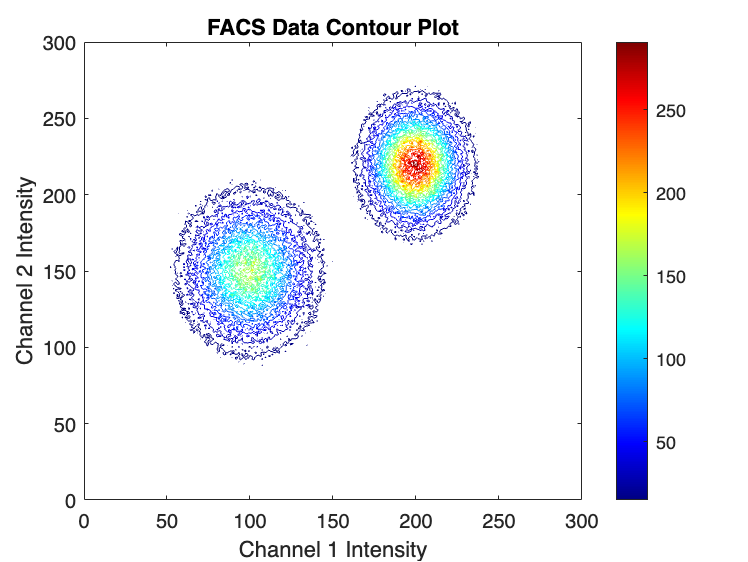

% Create a 2D histogram (density)
edges = linspace(0, 300, 300);
density = hist3([channel1, channel2], 'Edges', {edges, edges});

% Generate the contour plot
figure;
contour(edges, edges, density', 20);
xlabel('Channel 1 Intensity');
ylabel('Channel 2 Intensity');
title('FACS Data Contour Plot');
colormap(jet);
colorbar;

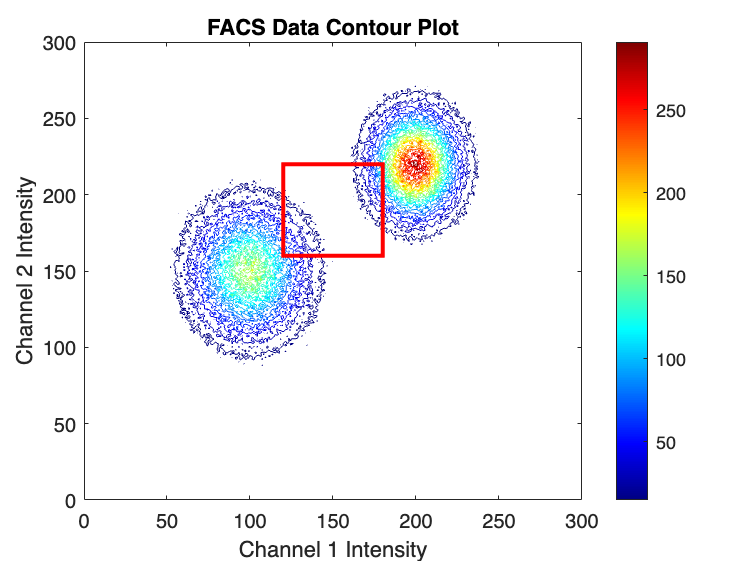

% Define gate boundaries (adjust these values as needed)
gate_x = [120, 180]; % Boundaries for Channel 1
gate_y = [160, 220]; % Boundaries for Channel 2

% Plot the gate as a rectangle
hold on;
rectangle('Position', [gate_x(1), gate_y(1), diff(gate_x), diff(gate_y)], 'EdgeColor', 'r', 'LineWidth', 2);
hold off;


% Apply gate to data (logical indexing to find cells within the gate)
gate_idx = (channel1 > gate_x(1)) & (channel1 < gate_x(2)) & ...
           (channel2 > gate_y(1)) & (channel2 < gate_y(2));

% Display the number of cells within the gate
num_cells_in_gate = sum(gate_idx);
disp(['Number of cells within the gate: ', num2str(num_cells_in_gate)]);

Number of cells within the gate: 50057
